# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 
load data_Exercice11

## Partie 1

N_centrales = length(A);
N_demandes = 10;
Demandes = linspace(sum(Pmin),sum(Pmax),10)'; % on va de la puissance min installable jusqu'à la puissance max 
Cout_prod = @(P) A'*P.^2 + B'*P + sum(C);
Aineq = []; % les contraintes d'inégalité sont dans les bornes
bineq = [];
Aeq = ones(1,N_centrales);
Puissances = zeros(N_demandes,N_centrales);
Cout_opti = zeros(N_demandes,1);
lb = Pmin; % pour les contraintes inégalité
ub = Pmax;
P0 = (Pmax + Pmin)./2;
options = optimoptions('fmincon','Display','iter');
for k = 1:N_demandes
    beq = Demandes(k);
    [P,fval,flag,out] = fmincon(Cout_prod,P0,Aineq,bineq,Aeq,beq,lb,ub,'',options);
    Puissances(k,:) = P;
    Cout_opti(k) = fval;
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.837164e+05    3.585e+02    6.931e+02
    1      12    3.476969e+05    3.476e+02    5.579e+02    2.895e+01
    2      18    1.693032e+05    1.611e+02    5.379e+02    9.572e+01
    3      24    1.444372e+05    1.353e+02    5.425e+02    3.903e+01
    4      30    1.438516e+05    1.346e+02    1.845e+02    5.506e-01
    5      36    1.334992e+05    1.185e+02    1.933e+02    8.483e+00
    6      42    1.130614e+05    8.709e+01    1.847e+02    2.095e+01
    7      48    1.124631e+05    8.599e+01    1.825e+02    8.682e-01
    8      54    1.118415e+05    8.474e+01    1.774e+02    7.421e-01
    9      60    1.113569e+05    8.373e+01    1.774e+02    7.713e-01
   10      66    8.614343e+04    1.027e+01    9.264e+01    5.304e+01
   11      72    8.449329e+04    2.485e+00    1.163e+01    7.864e+00
   12      78    8.446961e+04    2.361e+00    9

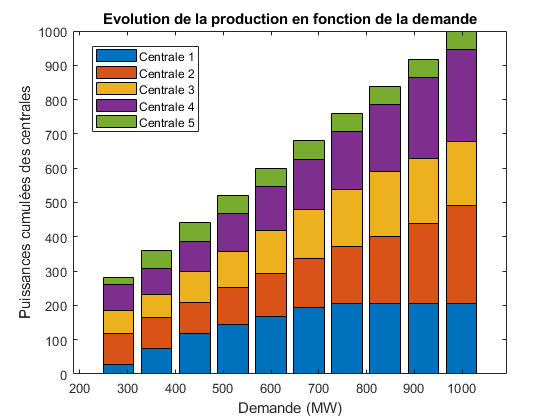

figure 
bar(Demandes,Puissances,'stacked')
xlabel('Demande (MW)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution de la production en fonction de la demande']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

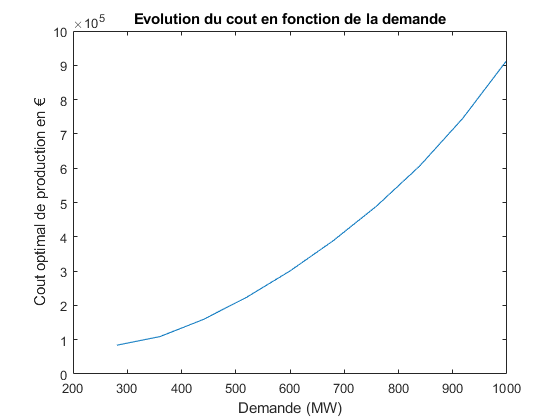

plot(Demandes,Cout_opti)
xlabel('Demande (MW)')
ylabel('Cout optimal de production en €')
title(sprintf(['Evolution du cout en fonction de la demande']))

## Partie 2

Demande = 400;
beq1 = Demande;
Pollution = @(P) D'/24*P.^2 + E'/24*P + sum(F);
[P1,C1,flag1,out1] = fmincon(Cout_prod,P0,Aineq,bineq,Aeq,beq1,lb,ub,'',options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.837164e+05    2.395e+02    6.931e+02
    1      12    3.523768e+05    2.325e+02    5.587e+02    2.761e+01
    2      18    3.271988e+05    2.122e+02    4.874e+02    1.214e+01
    3      24    2.444169e+05    1.230e+02    4.127e+02    9.025e+01
    4      30    2.405470e+05    1.204e+02    3.930e+02    3.476e+00
    5      36    1.406370e+05    5.830e+00    2.885e+02    8.852e+01
    6      42    1.357483e+05    4.186e+00    2.045e+02    3.922e+01
    7      48    1.336558e+05    3.170e+00    2.012e+02    1.321e+01
    8      54    1.336392e+05    3.156e+00    7.104e+01    7.341e-02
    9      60    1.334642e+05    2.923e+00    4.443e+01    5.760e-01
   10      66    1.314551e+05    5.684e-14    2.051e-01    6.725e+00
   11      72    1.314550e+05    0.000e+00    4.477e-03    9.540e-03
   12      78    1.314550e+05    0.000e+00    2

Pol1 = Pollution(P1);
[P2,Pol2,flag2,out2] = fmincon(Pollution,P0,Aineq,bineq,Aeq,beq1,lb,ub,'',options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    1.160437e+04    2.395e+02    2.771e+01
    1      12    6.313282e+03    8.666e+01    2.621e+01    7.438e+01
    2      18    4.791908e+03    4.261e+01    2.383e+01    2.847e+01
    3      24    4.777942e+03    4.230e+01    2.123e+01    3.630e-01
    4      30    4.027051e+03    2.638e+01    1.320e+01    2.674e+01
    5      36    4.021054e+03    2.609e+01    6.249e+00    1.752e-01
    6      42    3.681537e+03    5.684e-14    3.011e+00    1.753e+01
    7      48    3.664509e+03    0.000e+00    2.481e+00    5.952e+00
    8      54    3.654728e+03    0.000e+00    3.019e-01    8.849e+00
    9      60    3.654567e+03    0.000e+00    2.387e-01    3.774e-01
   10      66    3.654215e+03    5.684e-14    8.239e-02    1.666e+00
   11      72    3.654169e+03    0.000e+00    5.388e-04    8.488e-01
   12      78    3.654169e+03    0.000e+00    2

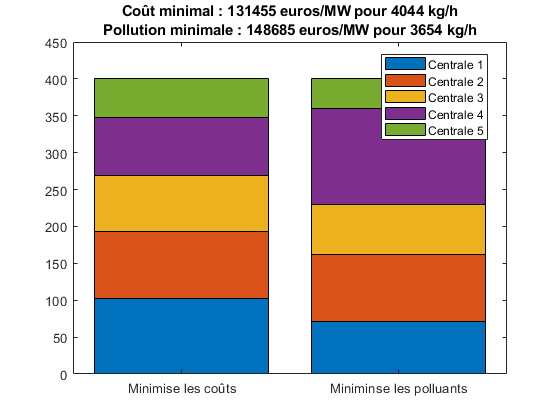

C2 = Cout_prod(P2);
Critere = categorical({'Minimise les coûts';'Miniminse les polluants'});
Critere =reordercats(Critere,{'Minimise les coûts';'Miniminse les polluants'}); % pour bien afficher le min coût à gauche (j'aime l'argent)
figure
bar(Critere,[P1,P2],'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
     C1,Pol1,C2,Pol2))

## Partie 3

N_points = 10;
% Méthode des pondérations
Couts1 = zeros(1,N_points);
Pollutions1 = zeros(1,N_points);
Puissances1 = zeros(N_centrales,N_points);
taxes = 24*linspace(0.1,0.5,N_points); % on pondère avec la taxe ramenée en €/(kg/h) 
f = @(P,x) Cout_prod(P) + taxes(x)*Pollution(P);
for k = 1:N_points
    [P,fval,flag,out] = fmincon(@(P) f(P,k),P0,Aineq,bineq,Aeq,beq1,lb,ub,'',options);
    Couts1(k) = fval;
    Pollutions1(k) = Pollution(P);
    Puissances1(:,k) = P;
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    4.115669e+05    2.395e+02    7.440e+02
    1      12    3.785851e+05    2.330e+02    5.975e+02    2.747e+01
    2      18    3.473464e+05    2.094e+02    5.253e+02    1.455e+01
    3      24    2.804868e+05    1.463e+02    3.770e+02    7.542e+01
    4      30    2.741030e+05    1.415e+02    3.770e+02    4.042e+00
    5      36    1.594359e+05    1.745e+01    2.779e+02    8.220e+01
    6      42    1.593147e+05    1.742e+01    2.762e+02    3.070e-01
    7      48    1.419394e+05    5.684e-14    9.965e+01    4.114e+01
    8      54    1.412315e+05    0.000e+00    7.758e+01    1.931e+01
    9      60    1.410568e+05    5.684e-14    4.009e+01    7.087e+00
   10      66    1.410561e+05    0.000e+00    1.147e+00    3.442e-01
   11      72    1.410561e+05    5.684e-14    3.355e-03    9.171e-03
   12      78    1.410561e+05    5.684e-14    4

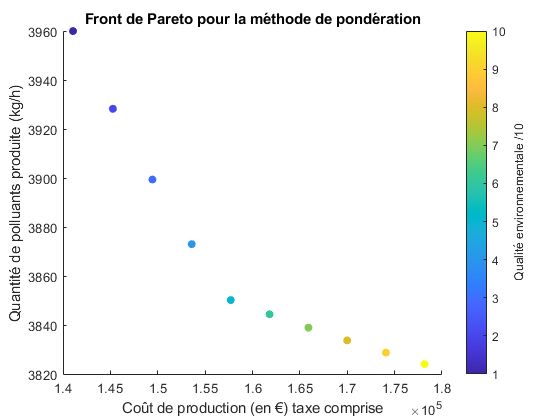

Z = linspace(1,10,N_points);
figure
scatter(Couts1,Pollutions1,[],Z,'filled')
colormap default
c = colorbar;
c.Label.String = 'Qualité environnementale /10';
xlabel('Coût de production (en €) taxe comprise')
ylabel('Quantité de polluants produite (kg/h)')
title('Front de Pareto pour la méthode de pondération')

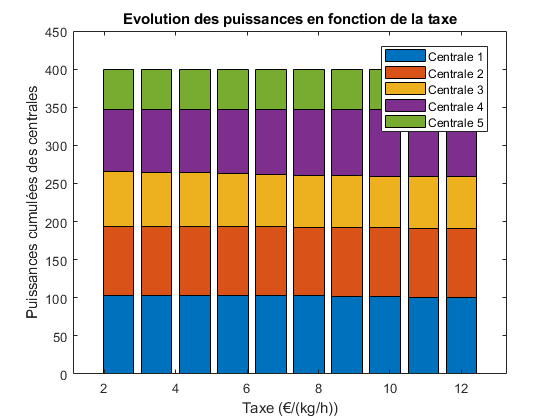

bar(taxes,Puissances1,'stacked')
xlabel('Taxe (€/(kg/h))')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution des puissances en fonction de la taxe']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

% Méthode des contraintes
seuils = linspace(90000,95000,N_points)/24; % on passe le seuil en kg/h
Couts2 = zeros(1,N_points);
Pollutions2 = zeros(1,N_points);
Puissances2 = zeros(N_centrales,N_points);
for k = 1:N_points
    [P,fval,flag,out] = fmincon(Cout_prod,P0,Aineq,bineq,Aeq,beq1,lb,ub,@(P) penalite(P,k,D,E,F,seuils),options);
    Couts2(k) = fval;
    Pollutions2(k) = Pollution(P);
    Puissances2(:,k) = P;
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    3.837164e+05    7.854e+03    9.503e+02
    1      12    3.480858e+05    7.594e+03    8.645e+02    3.775e+01
    2      18    1.688345e+05    2.323e+03    3.947e+02    1.023e+02
    3      24    1.670344e+05    2.203e+03    3.770e+02    3.709e+00
    4      30    1.606019e+05    1.840e+03    3.359e+02    8.003e+00
    5      36    1.565231e+05    1.644e+03    2.420e+02    8.746e+00
    6      42    1.485925e+05    1.175e+03    2.116e+02    1.829e+01
    7      48    1.477024e+05    1.114e+03    1.387e+02    1.661e+00
    8      54    1.371392e+05    5.892e+02    6.070e+01    1.562e+01
    9      60    1.371064e+05    5.874e+02    6.069e+01    5.134e-02
   10      66    1.366760e+05    5.497e+02    5.931e+01    1.382e+00
   11      72    1.325248e+05    1.096e+02    1.378e+01    1.821e+01
   12      78    1.325369e+05    1.026e+02    1

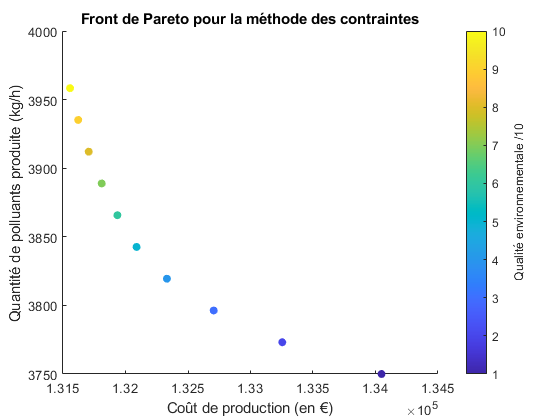

figure
scatter(Couts2,Pollutions2,[],Z,'filled')
colormap default
c = colorbar;
c.Label.String = 'Qualité environnementale /10';
xlabel('Coût de production (en €)')
ylabel('Quantité de polluants produite (kg/h)')
title('Front de Pareto pour la méthode des contraintes')

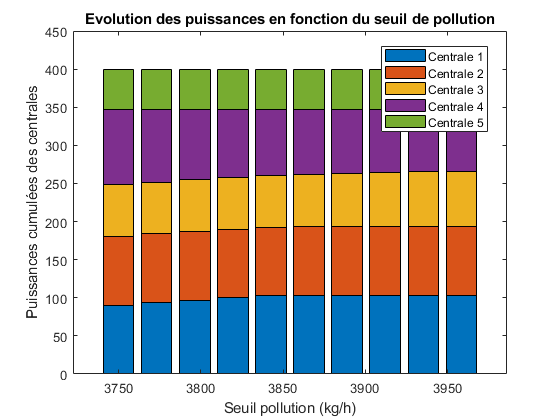

bar(seuils,Puissances2,'stacked')
xlabel('Seuil pollution (kg/h)')
ylabel('Puissances cumulées des centrales')
title(sprintf(['Evolution des puissances en fonction du seuil de pollution']))
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

Avec les valeurs de taxes choisies l'optimum se situe entre 140 et 180 k€ taxes comprises. Les puissances des différentes centrales ne varient presque pas.

Pour la méthode avec des seuils de pollution, l'optimum se situe entre 131 et 134 k€. La puissance de la centrale 1 diminue légèrement au profit de la centrale 4 quand le seuil est plus contraignant. C'est cohérent avec la partie 2 car on y voyait que la centrale 1 était plus intéressante économiquement mais très polluante là où la centrale 4 est peu rentable mais également moins polluante.

## Annexe : aides pour les graphiques

Ci dessous des codes qui peut vous inspirer pour le tracé de graphiqes. Remerciements à Mathieu Milhé.

% exemple 1 (valeurs numériques aléatoires choisies)
% Demande = 300:100:500;
% P=[70 95 120
%    70 85 105
%    70 85 100
%    50 80 100
%    40 55 75];
% 
% figure
% bar(Demande,P,'stacked')
% xlabel('Demande (MW)')
% ylabel('Puissances cumulées des centrales')
% title(sprintf(['Evolution de la bla bla bla ...en fonction de la demande']))
% legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")

% exemple 2 (valeurs numériques aléatoires choisies)
% x = categorical([{'Coût 1'}, {'Pollution 1'}]);
% P = [100 88 77 76 45];
% Q = [81 90 33 165 54];
% C1=1e5; Pol1=8e4; C2=1.5e5; Pol2=7e4;
% bar(x,[P;Q],0.3,'stacked')
% legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
% title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
%     C1,Pol1,C2,Pol2))

% exemple 3 (valeurs numériques aléatoires choisies)
% X=1e5:0.2e5:2e5;
% Y=[12 11 9 8 7 5].*1e3;
% Z=1:6;
% scatter(Y,X,[],Z)
% colormap winter
% c = colorbar;
% c.Label.String = 'Niveau de bl bla bla';
% xlabel('abscisse (unité)')
% ylabel('ordonnée (unité)')
% title('Front de Pareto pour bla bla bla avec bla bla variant entre bla bla et bla bla')

## Fonction contraintes non linéaires

function [c,ceq] = penalite(P,x,D,E,F,s)
c = D'/24*P.^2 + E'/24*P + sum(F) - s(x); % la pollution ne peut pas dépasser le seuil
ceq = [];
end